# MXB201 Project Background Reading

## Introduction

Magnetic resonance imaging, or MRI, is a medical imaging technique in which patients are exposed to a strong magnetic field, typically within a specialised machine called an MRI scanner.  The response of the human tissue – in particular, the magnetisation of the hydrogen protons within the water in the tissue – to gradients in this field is measured through the induced voltage in the receiver coils of the device. This induced voltage comprises the **signal** measured by the MRI machine.  By applying magnetic field gradients at different directions through the patient, the response to these gradients (i.e. the change in the measured signal) can be detected, and a three-dimensional reconstruction of the subject can be recovered.  This three-dimensional reconstruction comes in the form of numerical values (e.g. diffusivity -- see below) recorded at each *voxel*, the three-dimensional analogue of a pixel.

A key advantage of MRI over other medical imaging technologies such as X-ray and CT scans is that the resonant frequency of hydrogen protons is in the radio-frequency (RF) range, so that the electromagnetic pulses required to induce resonance are perfectly safe even for extended or repeated exposures.

## Part I: MRI Diffusion Tensor Imaging

There are many different *sequences* of RF pulses and gradients that can be used in modern MRI scanners.  Each type of sequence is designed to pick up on one particular property of the tissue.  We will be interested in *diffusion weighted* MRI, which is designed to measure the diffusivity of water (the rate at which water molecules diffuse, or "spread out") at different locations in the tissue.  Specifically, we will study diffusion weighted MRI scans of the human brain.  Mapping the water diffusivity throughout a patient's brain can be a way of diagnosing conditions such as ischaemic stroke, differentiating benign lesions from malignant tumours, and grading certain types of diffuse tumour cells.

The basic physics is that the acquired signal $S$ decays exponentially as a function of:

- the diffusion tensor $\mathbf{D}$ (mm$^2$/s),

- the direction of the diffusion sensitising gradient pulse $\mathbf{g}$ (which is a unit vector in $\mathbb{R}^3$), and

- a parameter $b$ (s/mm$^2$) called the diffusion-weighting factor that can be set by the machine operator (see below for more details on this "$b$-value").

The equation for this exponential decay is given by

$S = S_0 \exp({-b\, \textbf{g}^\textrm{T}\mathbf{D}\mathbf{g}})$.

Note on terminology: $\mathbf{D}$ is invariably referred to as the diffusion "tensor", but you can safely substitute the word "SPD matrix" in your head for "tensor".  $\mathbf{D}$ is simply a $3 \times 3$ symmetric positive definite matrix.

The process goes roughly like this.  First, a signal $S_0$ is recorded without applying any diffusion sensitising gradient.  Then, a diffusion sensitising gradient pulse is applied along a sequence of directions $\mathbf{g}_i$, one-by-one.  To ensure that a good three-dimensional representation of the diffusion tensor can be obtained, there may be 50 or more directions used, which is why having a brain MRI scan often requires the patient to spend up to an hour in the machine.  The "$b$-value" is a scalar that absorbs all the details about the gradient pulse other than its direction, such as its strength and timing.  The $b$-value is held constant for all the gradient pulses (a typical value is 1000 s/mm$^2$); all that changes throughout the scan are the directions $\mathbf{g}_i$.

Following the scan, the following data will be available:

- The signal $S_0$ that was recorded for each voxel before any gradient pulses were applied.

- The single $b$-value that was used for all gradient pulses.

- The directions $\mathbf{g}_i$ that were used for each gradient pulse.

- For each gradient direction $\mathbf{g}_i$, the signal $S$ that was recorded for each voxel.

The objective is to use this data to estimate the diffusion tensor $\mathbf{D} \in \mathbb{R}^{3 \times 3}$ at each voxel.  For the purposes of this project, you will process just a single slice of the full scan along the axial plane for a particular patient.  Hence, although we will stick to standard terminology, you can mentally substitute the word "pixel" for "voxel" if you prefer.

### Least squares problem

This section follows the presentation of Jiang, et al. [1].  You can download this paper using the link provided.

Being a symmetric matrix, $\mathbf{D}$ has only six independent components:


$$\mathbf{D} = \left[\matrix{D_{xx} & D_{xy} & D_{xz} \cr D_{xy} & D_{yy} & D_{yz} \cr D_{xz} & D_{yz} & D_{zz}}\right]$$


The six values $D_{xx}$, $D_{yy}$, $D_{zz}$, $D_{xy}$, $D_{xz}$, $D_{yz}$ are the only unknowns in the governing equation

$S = S_0 \exp({-b\, \textbf{g}^\textrm{T}\mathbf{D}\mathbf{g}})$.

After dividing through by $S_0$ (which is known), and taking logs,

$\log\left(\frac{S}{S_0}\right) = -b\, \mathbf{g}^\textrm{T} \mathbf{D} \mathbf{g}$.

Within each voxel, this equation is assumed to hold for each of the directions $\mathbf{g}_i$.  Suppose that 64 directions were used.  Then estimating $\mathbf{D}$ from the signal data within each voxel is a least squares problem, with 64 equations (one per gradient direction) and six unknowns (the components of $\mathbf{D}$).

As outlined in Jiang, et al. [1], you treat the six unknowns as a vector $\tilde{\mathbf{D}} = [D_{xx}\ D_{yy}\ D_{zz}\ D_{xy}\ D_{xz}\ D_{yz}]^\textrm{T}$ and form the $64 \times 6$ coefficient matrix $\textbf{A}$ and $64 \times 1$ right-hand-side vector $\textbf{B}$, to obtain the overdetermined linear system

$\mathbf{A}\tilde{\mathbf{D}} = \mathbf{B}$.

Jiang, et al. suggest solving this system using the pseudoinverse, but that's not necessary.  You can simply use backslash in MATLAB (which amounts to using a QR decomposition).  Be sure to mind your minus signs -- these have a tendency to go missing in Jiang et al.'s paper.

### Visualisation

Having obtained an estimate of the diffusion tensor $\mathbf{D}$ within each voxel, we can now visualise this field in a number of ways.  A good overview of possibilities is given at `MRIquestions.com` [2].

The key intuition is that since $\mathbf{D}$ is a symmetric positive definite matrix, its eigenvalues $\lambda_1, \lambda_2, \lambda_3$ are real and its eigenvectors $\mathbf{v}_1, \mathbf{v}_2, \mathbf{v}_3$ are orthogonal.  The eigenvectors represent the principal directions of diffusion; the action of $\mathbf{D}$ can be thought of as a stretching along these three orthogonal axes.  The magnitude of this stretching is governed by the eigenvalues.  We assume the eigenvalues are ordered so that $\lambda_1 \ge \lambda_2 \ge \lambda_3$.

A sense of the magnitude of the diffusion at each voxel can be obtained by visualising the *mean diffusivity:* $\textrm{MD} = (\lambda_1 + \lambda_2 + \lambda_3) / 3$.  As an example, here we visualise a healthy adult brain, taken from the Human Connectome Project [3].  We can see regions of cerebrospinal fluid most brightly, because its mean diffusivity is largest.  Grey matter is the next brightest, and white matter is darkest.

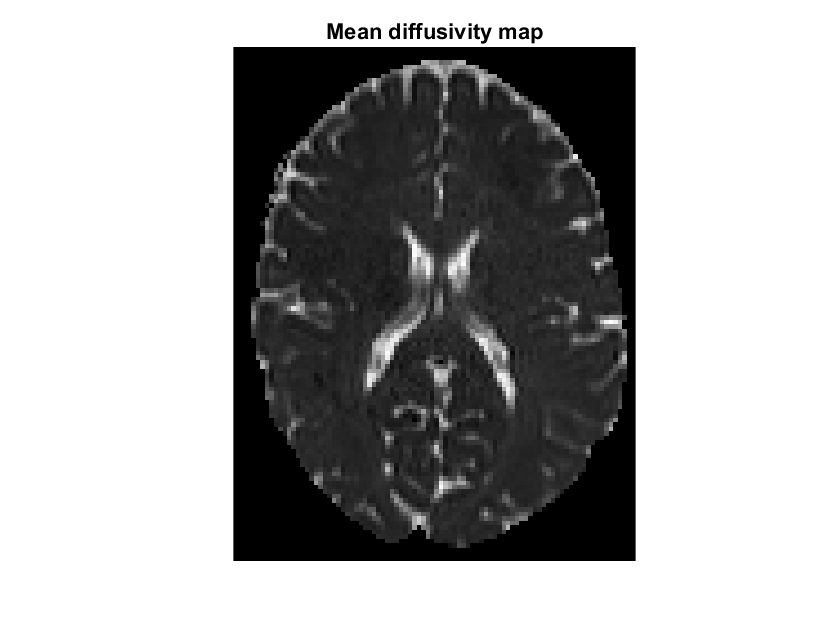

Also useful is a measure of the *anisotropy* of the diffusion: how different are the eigenvalues from one another?  The *fractional anisotropy* (FA) is a way to quantify this; formulas are given in the first two references [1] and [2].  An FA value of 0 indicates that $\lambda_1 = \lambda_2 = \lambda_3$, so that diffusion is equal in all directions, or *isotropic*.  The more *an*isotropic the diffusion, the closer FA gets to 1.  In this same healthy brain, the white matter stands out under the FA map, since the bundles of fibres that comprise white matter tend to facilitate diffusion along the fibres more strongly than across the fibres.

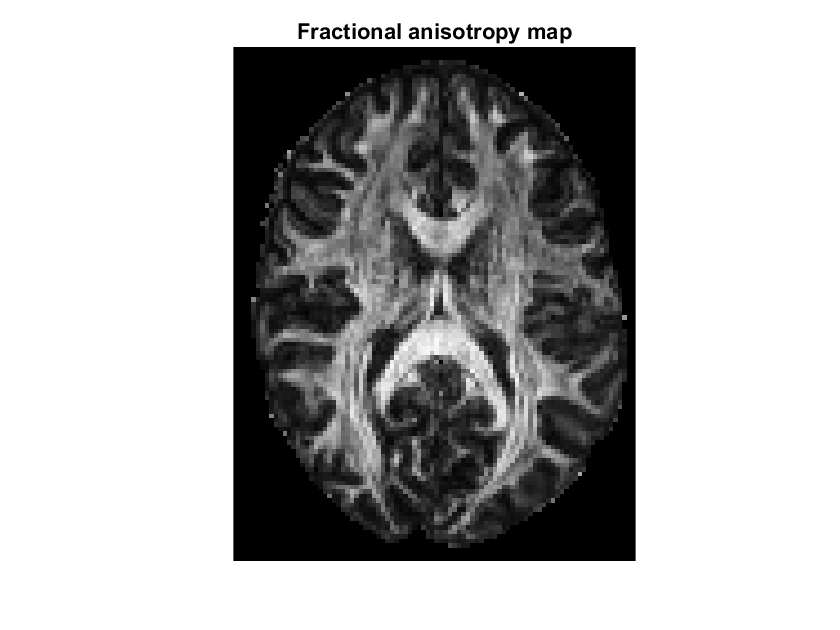

Finally there is the *principal diffusion direction*: the eigenvector $\mathbf{v}_1$ which is associated with the largest eigenvalue $\lambda_1$.  This is the direction in which diffusion is strongest.  It is a three-dimensional vector, so we need to be a bit creative to visualise it on a two-dimensional slice.  One idea is to use the three coordinates of $\mathbf{v}_1$ to determine the red, green, and blue pixel intensities, with an additional scaling by FA to control brightness.  Refer to reference [2] for details.  Here red indicates predominantly left-right diffusion, green is predominantly anterior-posterior (up-down on the page), and blue is predominantly head-foot (in-out of the page).

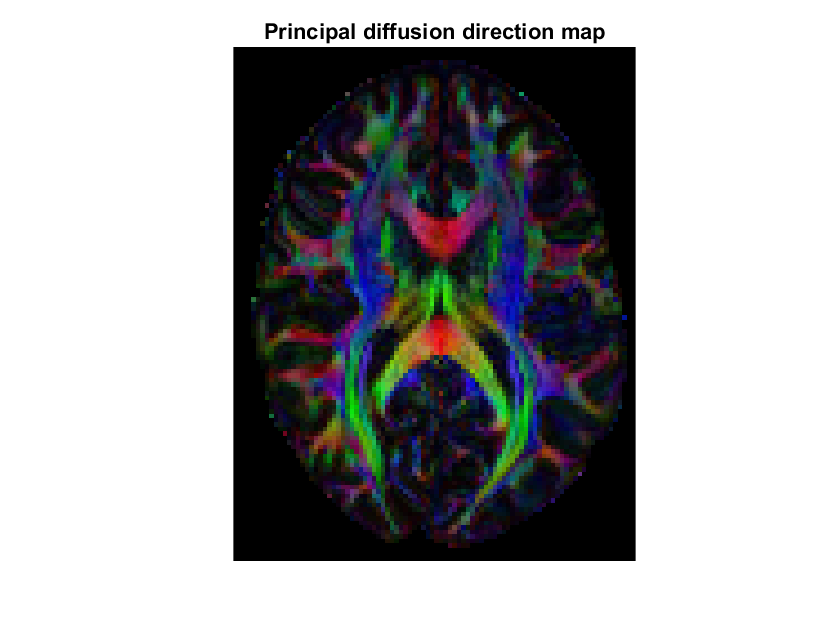

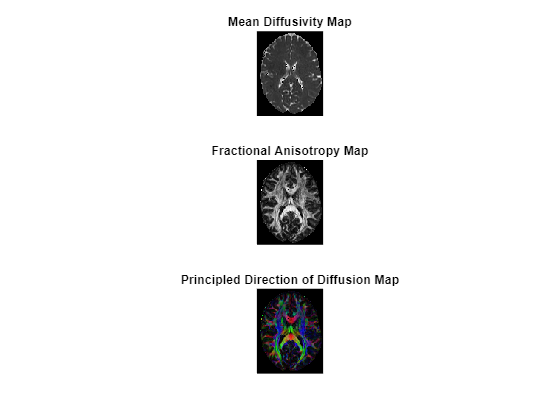

clear
load partI

[X,Y,num_dirs] = size(S);
assert(isequal(size(g), [num_dirs 3]));

% These arrays will be be filled in during the main loop below
MD  = nan(X, Y);    % mean diffusion
FA  = nan(X, Y);    % fractional anistropy
PDD = nan(X, Y, 3); % principal diffusion direction

xvec = X(:); yvec = Y(:);

%Creating Matrix D and Dtilde
syms D_xx D_xy D_xz D_yy D_yz D_zz real
D = [D_xx D_xy D_xz; D_xy D_yy D_yz; D_xz D_yz D_zz];
Dtilde= [D_xx D_yy D_zz D_xy D_xz D_yz]';

%% Construct matrix for the values of A, composed from 'g':

A= [g(:,1).^2, g(:,2).^2, g(:,3).^2, 2.*g(:,1).*g(:,2), 2.*g(:,1).*g(:,3), 2.*g(:,2).*g(:,3)];
% Compute the diffusion tensor for each pixel

for x = 1:X
    for y = 1:Y

        % If not within the mask, skip the pixel
        if ~mask(x, y), continue; end
        
        %Handling bad data - put something in here
        if S0(x,y) == 0 || any(S(x,y,:) <= 0)
        continue;
        end

        %Solving the least squares problem
        B= real(log(S./(S0)))*(1/-b);
        B_vec=squeeze(B(x,y,:));
        %Calculating D-tilde via backslash and least squares
        D_t= A\B_vec;
        %D_tilde_new= inv(A'*A)*A'*B_vec; %Different SLIGHTLY, look at extended decimal notation
       
        
        %Forming the diffusion tensor
        D=[D_t(1), D_t(4), D_t(5)
            D_t(4), D_t(2), D_t(6)
            D_t(5), D_t(6), D_t(3)];

       

        %Finding the eigenvalues and eigenvectors:
        [V, L]=eig(D);
        %eigen value decomposition
        ev=diag(L); 
        %Scale eignevalues to make them easier to visualise.
        ev = ev*400;

        %For SPD, eigenvalues must be non-negative.
        if any(ev<=0)
            if ev(1)<=0, ev(1)=0.0004; end
            if ev(2)<ev(1), ev(2)=ev(1)+0.0001; end
            if ev(3)<ev(2), ev(3)=ev(2)+0.0001; end     
        end
       
        
    
        %Calculating MD, FA and PDD;
        %Mean diffusivity
        MD(x,y)=mean(ev);
        %Fractional anisotropy
        FA(x,y)= sqrt( 1.5 * sum((ev - MD(x,y)).^2) / sum(ev.^2) );
        %principal diffusion direction
        [~, idx] = max(ev);
        PDD(x,y,:) = V(:,idx);

        %Removing NaN FROM THE DATA 
        PDD(isnan(PDD))=0;
        FA(isnan(FA))=0;
    end
end


%Plot mean diffusivity, fractional anisotropy and principal diffusion
%direction maps
figure
tiledlayout(3,1)
nexttile;
imshow(MD, []); %auto scales
title('Mean Diffusivity Map');
nexttile;
imshow(FA);
title('Fractional Anisotropy Map');
nexttile;

%Creating an RGB map for diffusion map:
RGB=zeros(X,Y,3);
for c=1:3
    RGB(:,:,c)= abs(PDD(:,:,c).*FA);
end
imshow(RGB);
title('Principled Direction of Diffusion Map');


$$\tilde{\mathbf{D}} = [D_{xx}\ D_{yy}\ D_{zz}\ D_{xy}\ D_{xz}\ D_{yz}]^\textrm{T}$$



$$\mathbf{D} = \left[\matrix{D_{xx} & D_{xy} & D_{xz} \cr D_{xy} & D_{yy} & D_{yz} \cr D_{xz} & D_{yz} & D_{zz}}\right]$$


## Part II: Feature Extraction

Like many fields, healthcare is experiencing a digital revolution.  The possibility of having large, linked sets of patient data means that machine learning algorithms may be able to supplement expert diagnoses by learning the warning signs of disease by training on these large data sets.

In the present application, we anticipate that there would be data from MRI scans of many patients stored in the database, with which to train a machine learning algorithm.  We will continue to simplify matters and deal only with scalar values for single slices of the brain -- so, greyscale images such as the MD or FA maps above.  Each patient's single slice would be stored as an $r \times c$ matrix.

We anticipate that much of the data in these $rc$ pixels is "uninteresting" from a diagnostic point of view, and only particular features are important (such as an unexplained dark spot in the FA map, which might be suggestive of damage or displacement of the normal white matter fibre bundles).  Suppose we have $N$ such images, corresponding to $N$ different patients; some will be healthy brains, some diseased.  One approach to building a machine learning system on this data is to think of the entirety of the database of images as a single matrix $A \in \mathbb{R}^{rc \times N}$, where each column of $A$ is a patient's image reshaped into a very tall column vector in $\mathbb{R}^{rc}$.

Now for an abrupt switch.  From this point onwards, we are going to switch from thinking about greyscale images of human brains, to greyscale images of human *faces*.  Nothing of mathematical substance changes in doing so.  It is simply more convenient to use freely available online databases of human faces than it is to source suitable human patient data for this project.  Furthermore, much of the ideas in this section were initially developed with the goal of applying them to the problem of facial recognition.  Indeed, you can find much written about this topic online under the name "eigenfaces".

Just to be clear: each column of our matrix $A \in \mathbb{R}^{rc \times N}$ now represents an $r \times c$ greyscale image of person's face, standing in for our real application of a greyscale MRI brain scan image.  We'll speak only about faces from now on in this section, but at any time you can mentally substitute "brain scan" for "face" to remind yourself of the true application we have in mind.

The source of the images for this section is The Extended Yale Face Database B [4].

### Mean centring

One thing we can do immediately with the matrix $A$ is to calculate the *mean face*: simply take the average across all the columns.  The mean face, by its construction, will have very generic eyes, nose, mouth and so forth*.*  Here is the mean face taken from a particular data set comprising 1000 different images.

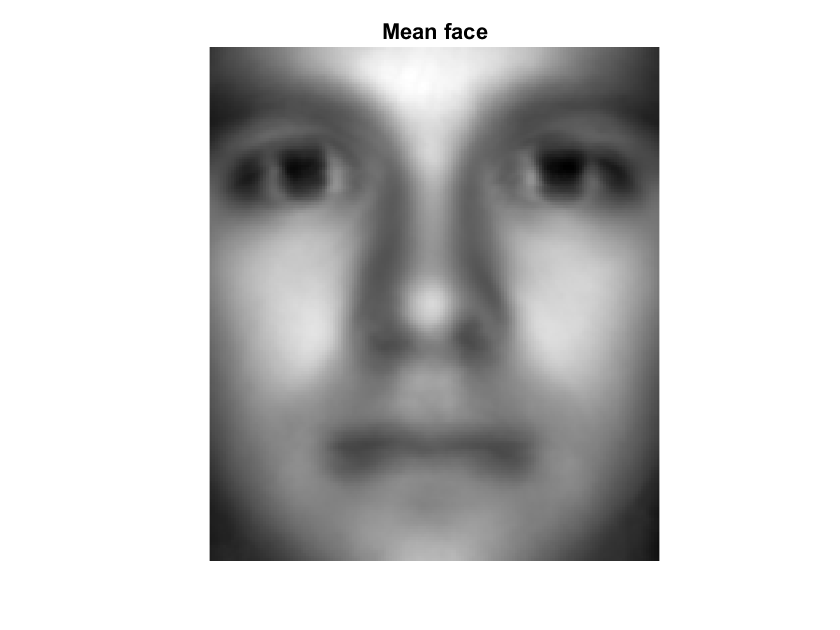

(Perhaps you think it looks almost "beautiful", which is a typical human response to noticing the near-perfect symmetry in the face, also due to the averaging process.)

If we subtract the mean face from all the columns in $A$ -- this is called *mean centring* -- we transform $A$ into a record of exactly how each face is different from the mean.

The hope is that this matrix will be of quite low effective rank: people tend to look quite like the "average person", plus or minus a weighted combination of only a few particular *features.  *It is these features that characterise one individual's facial appearance from another.

### Singular value decomposition

The most economical way to describe the *mean-centred* matrix $A$ using limited information is using the *reduced singular value decomposition*


$$A = U\Sigma V^T$$


where $U \in \mathbb{R}^{rc \times N}$ (the same dimensions as $A$), $V \in \mathbb{R}^{N\times N}$ and $\Sigma \in \mathbb{R}^{N\times N}$, with the singular values $\sigma_i$ ordered from largest to smallest on the diagonal of $\Sigma$.

The left singular vectors $u_i \in \mathbb{R}^{rc}$ are called *eigenfaces* (a bad choice of terminology, but perhaps "singular faces" doesn't have quite the same ring to it).  The leading eigenfaces (those corresponding to the largest singular values) represent the features that mostly strongly capture the differences between individuals' faces in the data set and the mean face.  Below we illustrate the first 20 eigenfaces for this data set.  The first few appear to be correcting for different lighting conditions.  Others look to be picking up on various prominent facial features.  Eigenface 13 is clearly the moustache eigenface!  Of course, the mathematics knows nothing about facial features.  The SVD merely finds the most economical way to approximate $A$ by matrices of lower rank.  The fact that these eigenfaces are picking out particular facial features tells us that, for example, presence or absence of a moustache has quite a lot of explanatory power when it comes to distinguishing human faces.

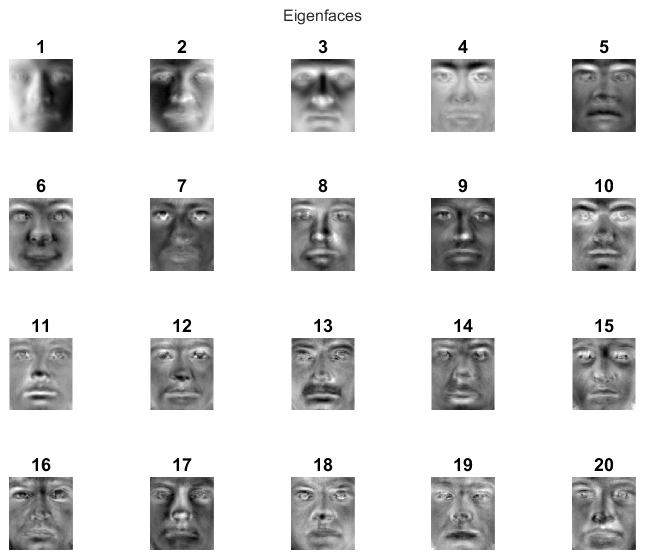

If the singular values decay rapidly, we might expect to get a good reconstruction of each individual's face by using linear combinations of only the first $\nu$ eigenfaces, $\nu \ll N$.  Each individual's face in the data set would therefore be identified with a $\nu$-dimensional coordinate vector, which is its projection onto the "eigenface space".

Back to digital health now: the idea is that these $\nu$-dimensional coordinate vectors could be used to train a machine learning system to identify warning signs of disease.  The "faces" are really going to be MRI brain scans, remember, and the features will be whatever the SVD identifies as the most distinguishing characteristics of human MRI brain scans.  With a very large dataset of pre-labelled healthy and diseased brain images, the system can try to learn which combinations of features are associated with greater incidence of (say) neurodegenerative disease.  New patients whose coordinate vectors have a lot in common with these learned "biomarkers" could then benefit from much earlier intervention than would be possible using only the diagnostic expertise of a human operator, with only a human lifetime's capacity for learning.

## References

[1] Jiang, H., Van Zijl, P. C., Kim, J., Pearlson, G. D., & Mori, S. (2006). DtiStudio: resource program for diffusion tensor computation and fiber bundle tracking. [Computer methods and programs in biomedicine, 81(2), 106-116](http://individual.utoronto.ca/ktaylor/DTIstudio_mori2006.pdf).

[2]  Allen D. Elster (2019).  Diffusion Tensor Imaging.  [https://mriquestions.com/dti-tensor-imaging.html](https://mriquestions.com/dti-tensor-imaging.html).

[3]  Ugurbil, K., Van Essen, D., et al.  (2017).  Human Connectome Project (Young Adult).  [https://www.humanconnectome.org/study/hcp-young-adult](https://www.humanconnectome.org/study/hcp-young-adult).

[4]  Lee, K. C., Ho, J., & Kriegman, D. J. (2005).  The Extended Yale Face Database B.  [http://vision.ucsd.edu/~iskwak/ExtYaleDatabase/ExtYaleB.html](http://vision.ucsd.edu/~iskwak/ExtYaleDatabase/ExtYaleB.html).